# DC motor position control: analysis

## Open-loop response

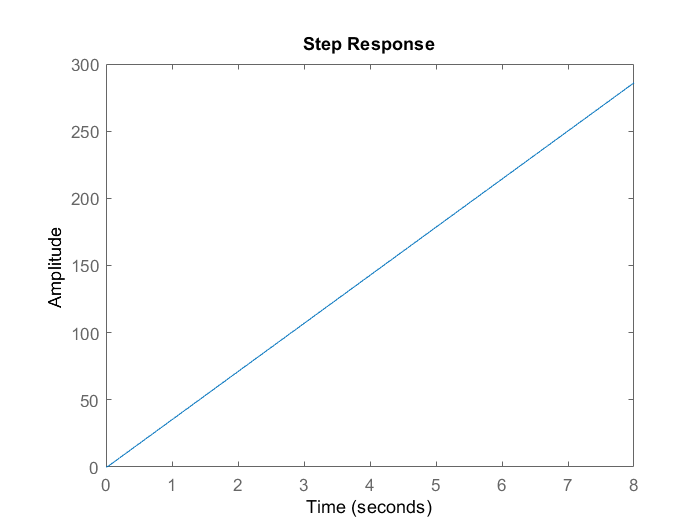

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;
s = tf('s');
sys = K/(s*((J*s+b)*(L*s+R)+K^2));
step(sys);

From the step response, we think the system is not stable, so we look at the poles of the open system.

pole(sys)

ans = 	1.0e+06 *

         0
   -1.4545
   -0.0001


Or we can use command isstable, 0 means not stable

isstable(sys)

ans = logical
   0


## Close-loop response

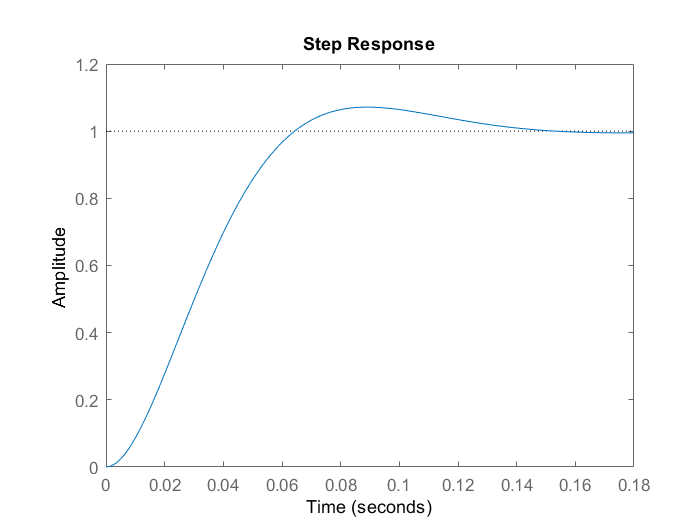

sys_cl = feedback(sys, 1);
step(sys_cl);

pole(sys_cl)

ans = 	1.0e+06 *

  -1.4545 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i


Lets look at the pzmap

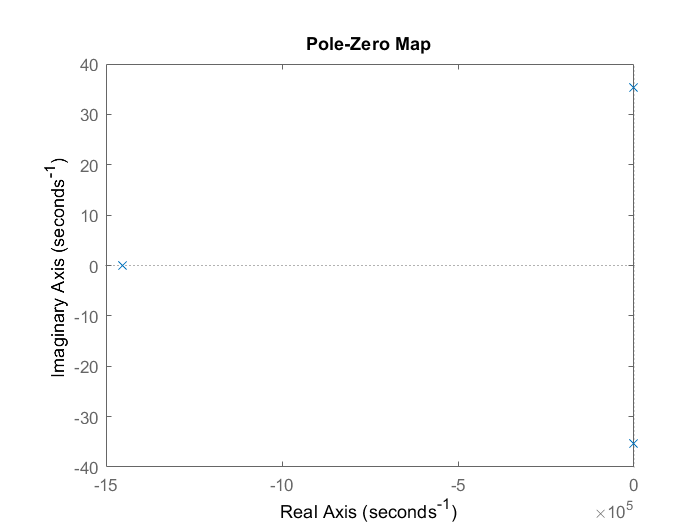

pzmap(sys_cl);

Let's us look at the damping 

damp(sys_cl)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.96e+01 + 3.53e+01i     6.43e-01       4.61e+01         3.38e-02    
 -2.96e+01 - 3.53e+01i     6.43e-01       4.61e+01         3.38e-02    
 -1.45e+06                 1.00e+00       1.45e+06         6.88e-07    


The dominant poles are the two poles close to the imaginary axis, and we can use these two poles to estimate the system.